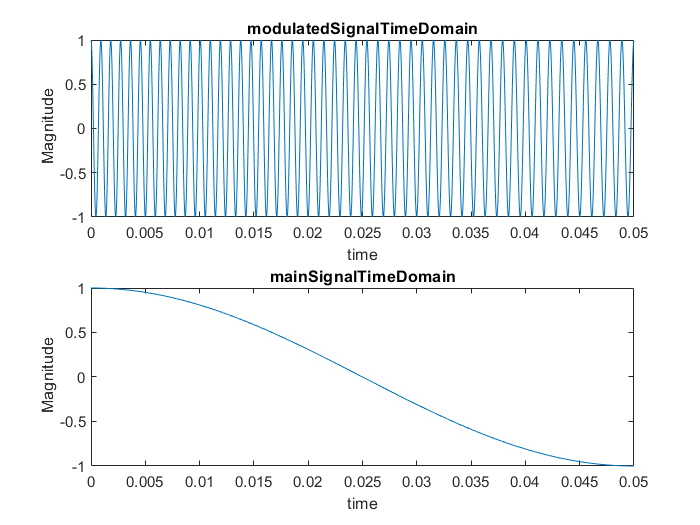

% part A
fs = 50000;
fm = 10;
fc = 1000;
fdelta = 100;
t = 0:1/fs:10;
x = cos(2*pi*fm*t);
integralSignal = Integral(x,fs);
v = cos(2*pi*fc*t+ 2*pi*fdelta*integralSignal);

[modulated,freqModulated] = standardFourierTransform(v,fs);
[main,freqMain] = standardFourierTransform(x,fs);


subplot(2,1,1);
plot(t(1:2500),v(1:2500));
title('modulatedSignalTimeDomain');
xlabel('time');
ylabel(' Magnitude');
subplot(2,1,2);
plot(t(1:2500),x(1:2500));
title('mainSignalTimeDomain');
xlabel('time');
ylabel(' Magnitude');

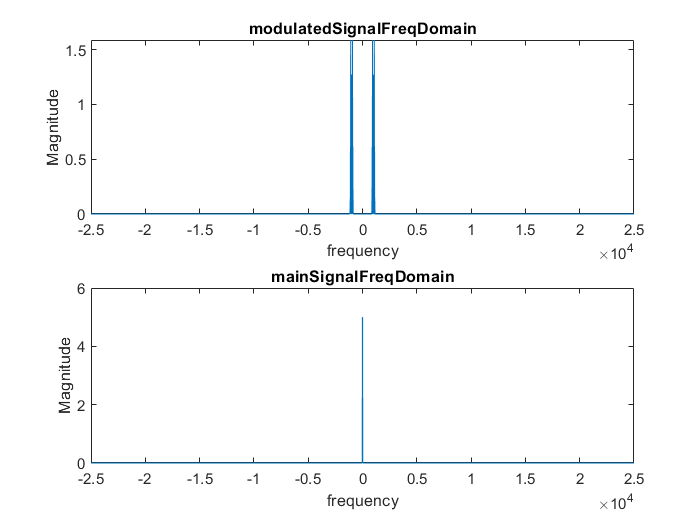

figure
subplot(2,1,1);
plot(freqModulated,abs(modulated));
title('modulatedSignalFreqDomain');
xlabel('frequency');
ylabel('Magnitude');
subplot(2,1,2);
plot(freqMain,abs(main));
title('mainSignalFreqDomain');
xlabel('frequency');
ylabel('Magnitude');

% calculating BW of 99 percent.
[dataSdf,dataFtransform] = sdf(v);

domain = linspace(-pi,pi,size(dataFtransform,2));
finalDomain = (domain/(2*pi))*fs;

powerAbs = abs(dataSdf);
totalEnergy = sum(powerAbs);
maxPower = max(powerAbs);
peakEnergy = find(powerAbs == maxPower);
centerFrequency = mean(peakEnergy);
power99 = totalEnergy*0.99;
freqIterator = 10;% 10Hz
boundedEnergy = calEnergy(powerAbs,centerFrequency,freqIterator);
while boundedEnergy < power99
    freqIterator = freqIterator + 10;
    boundedEnergy = calEnergy(powerAbs,centerFrequency,freqIterator);
end
startBound = centerFrequency - freqIterator;
endBound = centerFrequency + freqIterator;
normalizedStartBound = finalDomain(startBound:endBound);
SignalBW = ((normalizedStartBound(end)) - (normalizedStartBound(1)))/2

SignalBW = 1.1100e+03

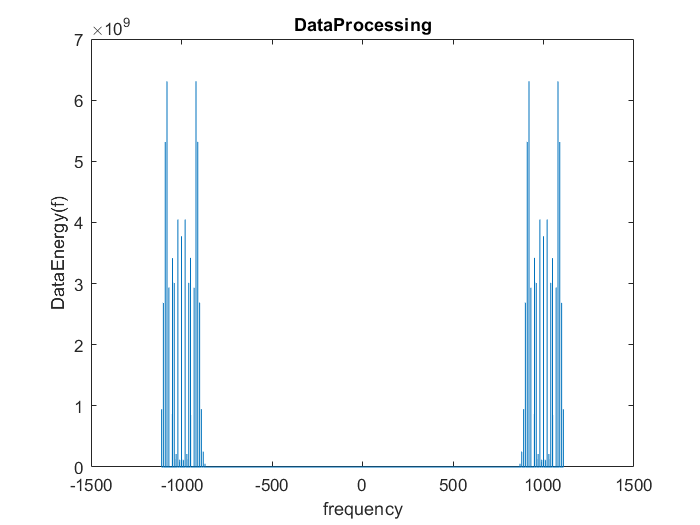

cutSignal = zeros(1,size(normalizedStartBound,2));
cutSignal(1:end) = powerAbs(startBound:endBound);
figure
plot(normalizedStartBound,cutSignal)
xlabel('frequency');
ylabel('DataEnergy(f)');
title('DataProcessing');

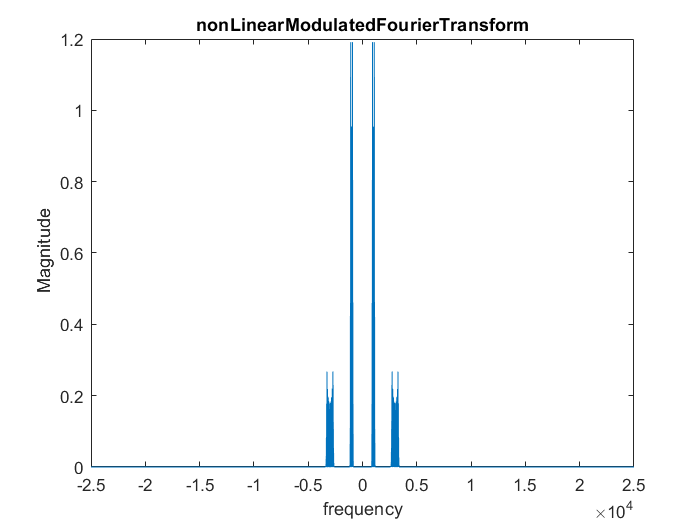

%part B
nonLinearBlockSignal = v.^3;
[nonLinearBLockFourierTransform,freq] = standardFourierTransform(nonLinearBlockSignal,fs);
plot(freq,abs(nonLinearBLockFourierTransform));
title('nonLinearModulatedFourierTransform');
xlabel('frequency');
ylabel(' Magnitude');

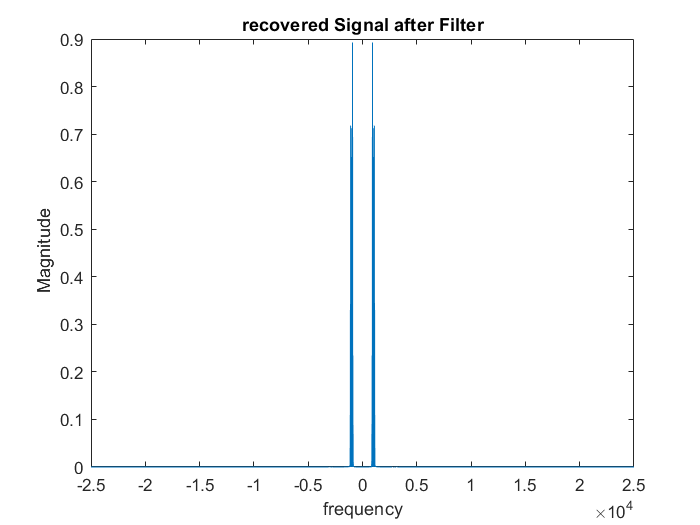

load('nonLinearBlock.mat');  % loading filter
recoveredNonlinearRemovedDelay = 3/4 * delaySyncer(nonLinearBlockSignal,nonLinearBlock);
[recoveredNonLinearRemovedDelay,freq] = standardFourierTransform(recoveredNonlinearRemovedDelay,fs);
plot(freq,abs(recoveredNonLinearRemovedDelay));
title('recovered Signal after Filter');
xlabel('frequency');
ylabel(' Magnitude');

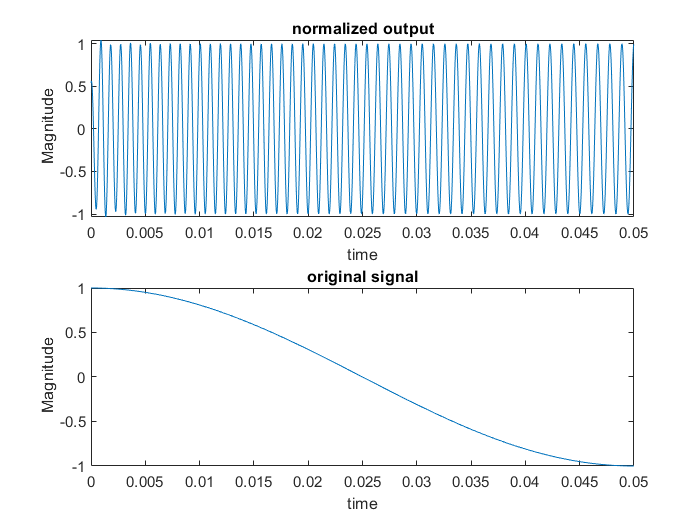

recoveredNonlinearRemovedDelay = recoveredNonlinearRemovedDelay/max(recoveredNonlinearRemovedDelay(2000:end)); %the gain that we use to recover exact original signal
tDomain = t(1:length(recoveredNonlinearRemovedDelay));
figure
subplot(2,1,1);
plot(tDomain(1:2500),recoveredNonlinearRemovedDelay(1:2500));
title(' normalized output ');
xlabel('time');
ylabel(' Magnitude');
subplot(2,1,2);
plot(t(1:2500),x(1:2500));
title(' original signal ');
xlabel('time');
ylabel(' Magnitude');

MSEerrorOfMainVSrecoveredNonLinear = immse(recoveredNonlinearRemovedDelay,v(1:length(recoveredNonlinearRemovedDelay)))

MSEerrorOfMainVSrecoveredNonLinear = 3.0520e-06

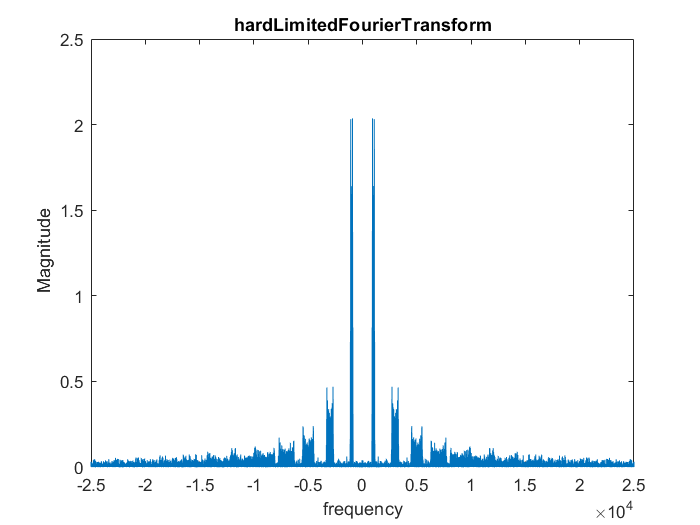

% part C
limited = sign(v);% Hard limiter
[limitedFourierTransform,freq] = standardFourierTransform(limited,fs);
figure
plot(freq,abs(limitedFourierTransform));
title('hardLimitedFourierTransform');
xlabel('frequency');
ylabel(' Magnitude');

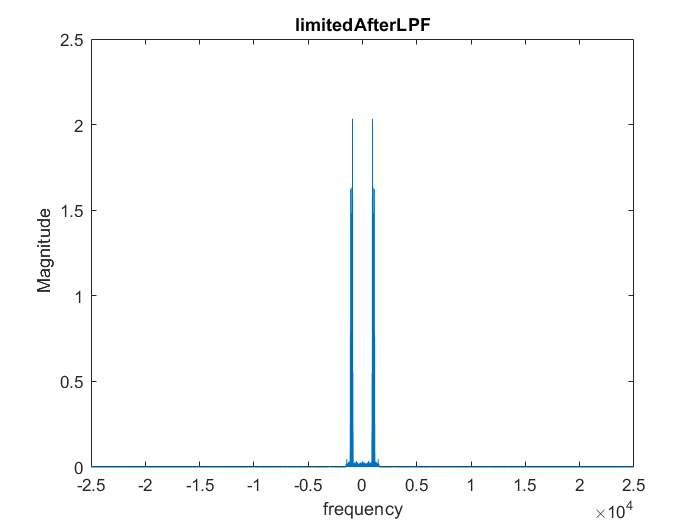

load('nonLinearBlock.mat');
afterLimitedDelayRemoved = delaySyncer(limited,nonLinearBlock);
[afterLimitedDelayRemovedFourierTransform,freq] = standardFourierTransform(afterLimitedDelayRemoved,fs);
figure
plot(freq,abs(afterLimitedDelayRemovedFourierTransform));
title(' limitedAfterLPF ');
xlabel('frequency');
ylabel(' Magnitude');

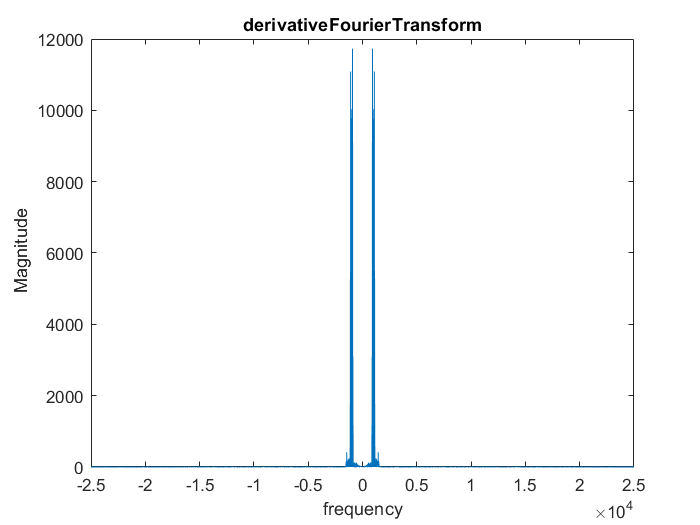

afterDerivater = derivative(afterLimitedDelayRemoved,fs);
[afterDerivaterFourierTransform,freq] = standardFourierTransform(afterDerivater,fs);
figure
plot(freq,abs(afterDerivaterFourierTransform));
title('derivativeFourierTransform');
xlabel('frequency');
ylabel(' Magnitude');


% [up,down] = envelope(afterDerivater);
% dcBlocker = dsp.DCBlocker;
% dcRemovedSignal = dcBlocker(transpose(up));
% x = x(1:length(dcRemovedSignal));
% MSEerror = immse(transpose(x),dcRemovedSignal)

tempSig = transpose(abs(afterDerivater));
dcRemoval = tempSig-mean(tempSig);
load('LPF.mat');
dcremoval = delaySyncer(dcRemoval,LPF);

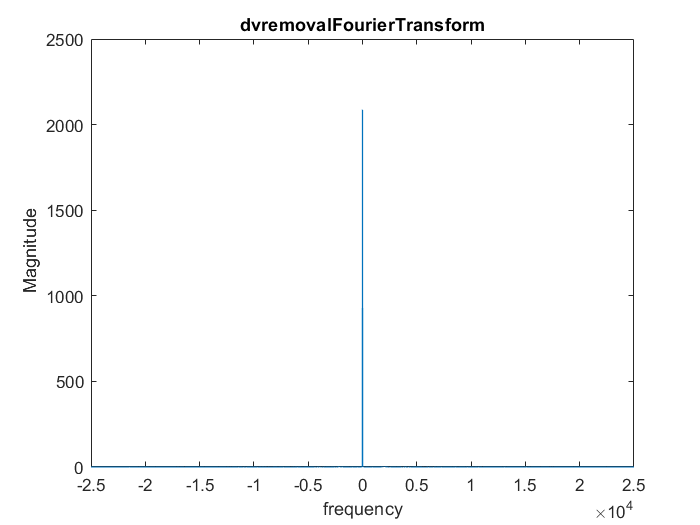

[dvremovalFourierTransform,freq] = standardFourierTransform(dcremoval,fs);
plot(freq,abs(dvremovalFourierTransform));
title('dvremovalFourierTransform');
xlabel('frequency');
ylabel(' Magnitude');

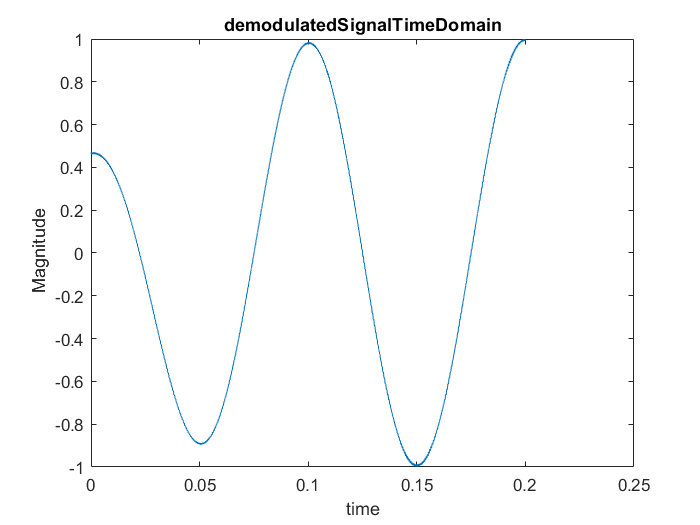

demodul = dcremoval/max(dcremoval);
plot(t(1:2*5001),demodul(1:2*5001));
title('demodulatedSignalTimeDomain');
xlabel('time');
ylabel(' Magnitude');

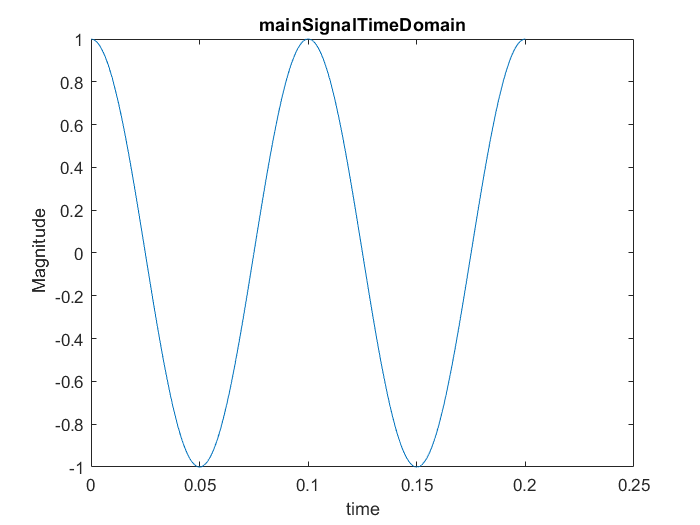

plot(t(1:2*5001),x(1:2*5001));
title('mainSignalTimeDomain');
xlabel('time');
ylabel(' Magnitude');

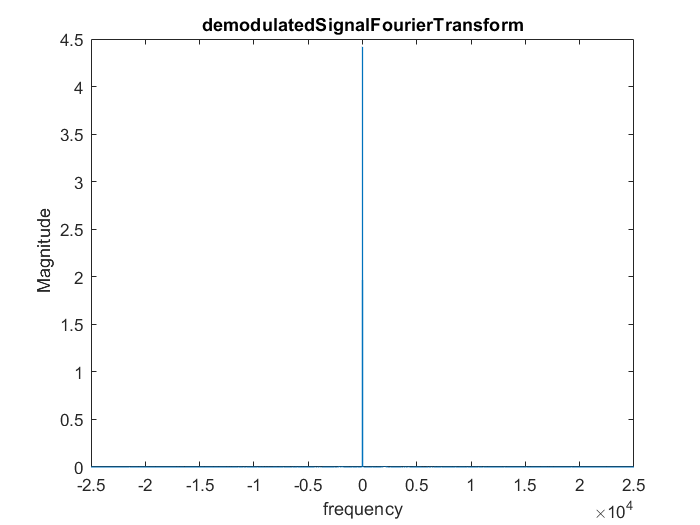

[demoduleFourierTransform,freq] = standardFourierTransform(demodul,fs);
plot(freq,abs(demoduleFourierTransform));
title('demodulatedSignalFourierTransform');
xlabel('frequency');
ylabel(' Magnitude');

tempX = x(1:length(demodul));
MSEerrorALLOfDomain = immse(demodul,transpose(tempX))

MSEerrorALLOfDomain = 4.3610e-04

MSEerrorCorrectDomain = immse(demodul(5001:2*5001),transpose(x(5001:2*5001)))

MSEerrorCorrectDomain = 4.5886e-05

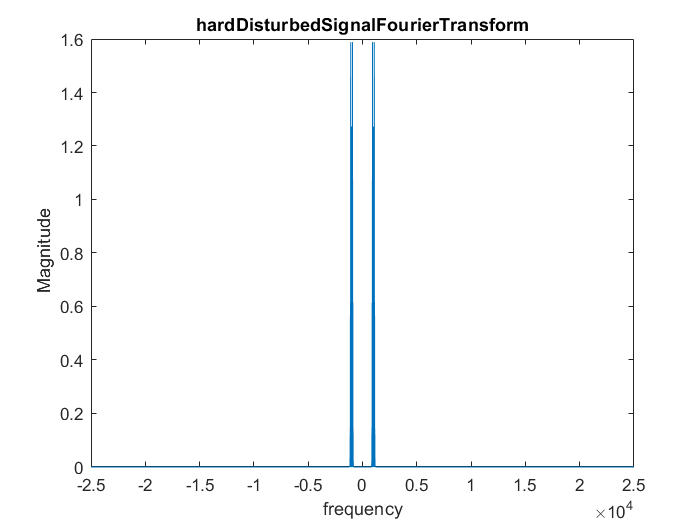

% part D
% first part : part C + disturbance
Ai = 0.1;
wi = 100;
wc = 2*pi*fc;
thi = pi/4;
disturbance = Ai*cos((wi+wc)*t+thi);
disturbed = v+disturbance;
[disturbedFourierTransform,freq] = standardFourierTransform(disturbed,fs);
plot(freq,abs(disturbedFourierTransform));
title('hardDisturbedSignalFourierTransform');
xlabel('frequency');
ylabel(' Magnitude');

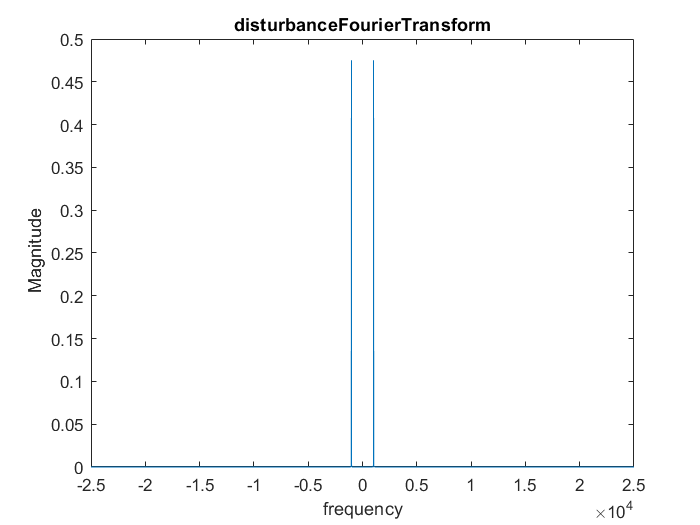

% ploting disturbance fourier
[disturbanceFourierTransform,freq] = standardFourierTransform(disturbance,fs);
figure('name','fourier of disturbance signal ');
plot(freq,abs(disturbanceFourierTransform));
title('disturbanceFourierTransform');
xlabel('frequency');
ylabel(' Magnitude');

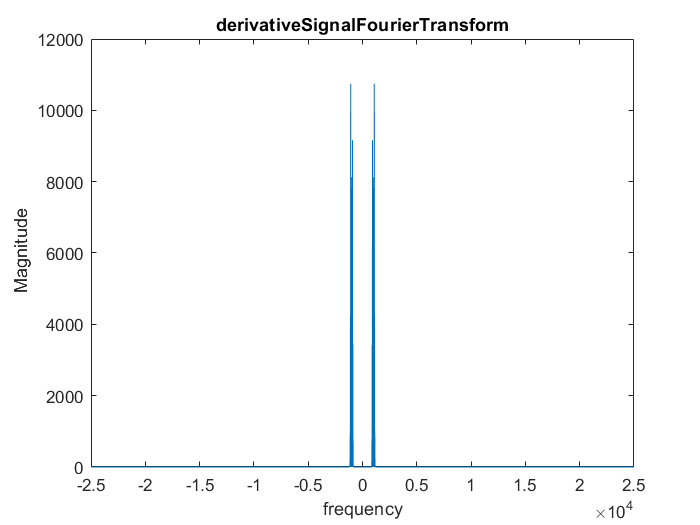



disturbedDerive = derivative(disturbed,fs);
[disturbedDerivativeFourierTransform,freq] = standardFourierTransform(disturbedDerive,fs);
plot(freq,abs(disturbedDerivativeFourierTransform));
title('derivativeSignalFourierTransform');
xlabel('frequency');
ylabel(' Magnitude');

tempSig = transpose(abs(disturbedDerive));
dcRemoval = tempSig-mean(tempSig);

load('LPF.mat');
dcremoval = delaySyncer(dcRemoval,LPF);

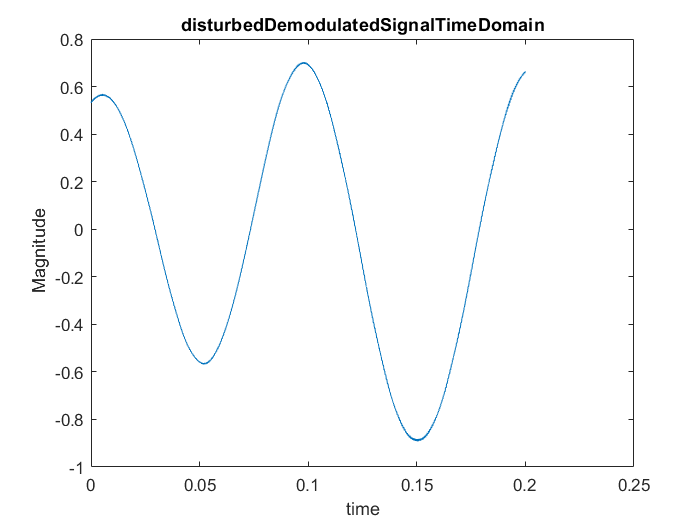

demodul = dcremoval/max(dcremoval);

plot(t(1:2*5001),demodul(1:2*5001));
title('disturbedDemodulatedSignalTimeDomain');
xlabel('time');
ylabel(' Magnitude');

plot(t(1:2*5001),x(1:2*5001));
title('mainSignalTimeDomain');
xlabel('time');
ylabel(' Magnitude');

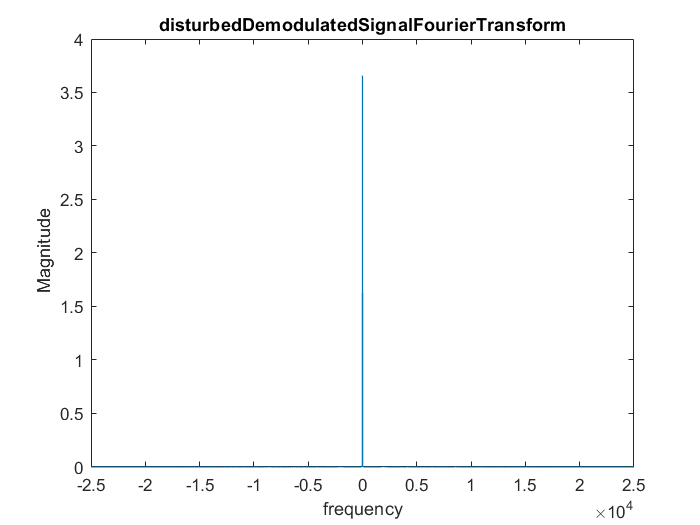


[disturbedDemoduleFourierTransform,freq] = standardFourierTransform(demodul,fs);
plot(freq,abs(disturbedDemoduleFourierTransform));
title('disturbedDemodulatedSignalFourierTransform');
xlabel('frequency');
ylabel(' Magnitude');


tempX = x(1:length(demodul));
MSEerrorALLOfDomain = immse(demodul,transpose(tempX))

MSEerrorALLOfDomain = 0.0541

MSEerrorCorrectDomain = immse(demodul(5001:2*5001),transpose(x(5001:2*5001)))

MSEerrorCorrectDomain = 0.0494

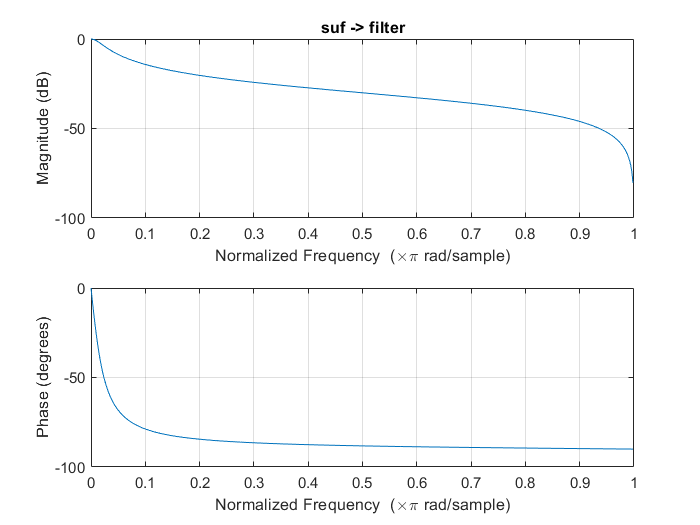

% pre/suf filters
%  second part : part C + disturbance + pre/suf filters!!!
[b,a] = butter(1, 1000/(fs));
figure()
freqz(b,a);
title('suf -> filter');

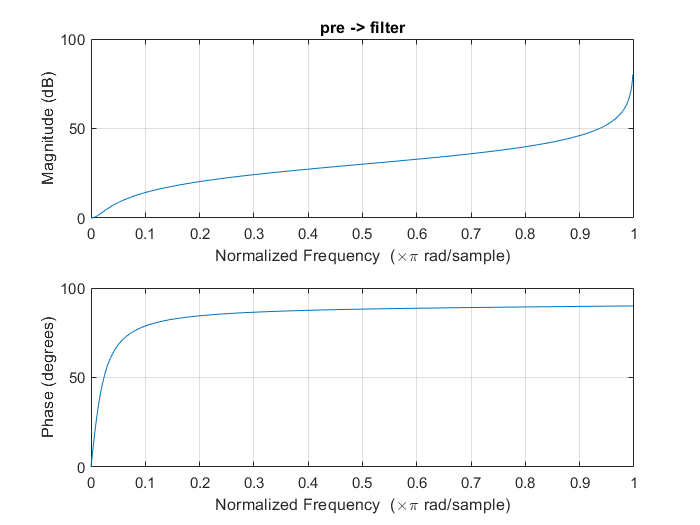

figure()
freqz(a,b);
title('pre -> filter');

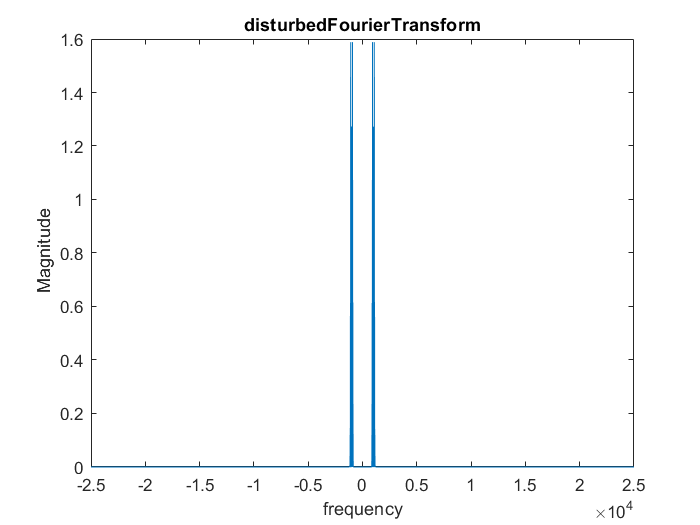

% adding pre/suf filters

gain = 100;
amplified = gain*filter(a,b,v);
disturbed = amplified+disturbance;
disturbed = (1/gain)*filter(b,a,disturbed);
[disturbedFourierTransform,freq] = standardFourierTransform(disturbed,fs);
figure
plot(freq,abs(disturbedFourierTransform));
title('disturbedFourierTransform');
xlabel('frequency');
ylabel(' Magnitude');

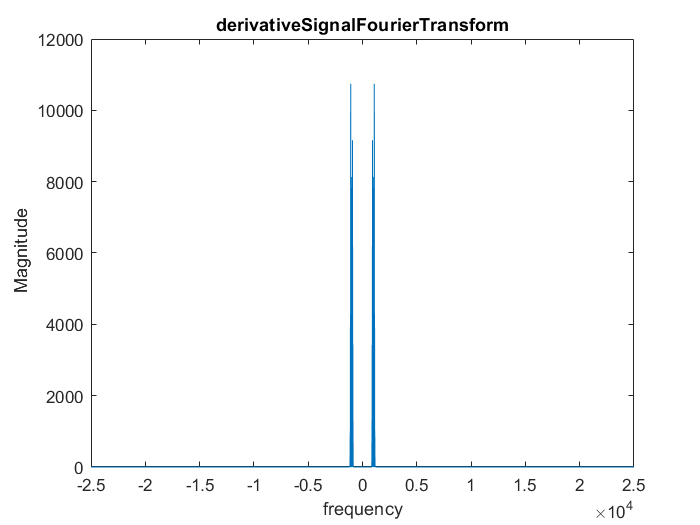


disturbedDerive = derivative(disturbed,fs);
[derivativeDisturbedFourierTransform,freq] = standardFourierTransform(disturbedDerive,fs);
figure
plot(freq,abs(derivativeDisturbedFourierTransform));
title('derivativeSignalFourierTransform');
xlabel('frequency');
ylabel(' Magnitude');


tempSig = transpose(abs(disturbedDerive));
dcRemoval = tempSig-mean(tempSig);

load('LPF.mat');
dcremoval = delaySyncer(dcRemoval,LPF);

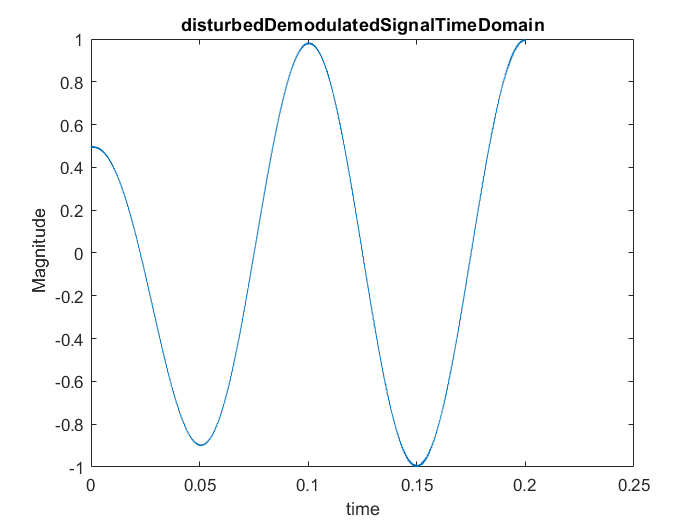

demodul = dcremoval/max(dcremoval);

plot(t(1:2*5001),demodul(1:2*5001));
title('disturbedDemodulatedSignalTimeDomain');
xlabel('time');
ylabel(' Magnitude');

plot(t(1:2*5001),x(1:2*5001));
title('mainSignalTimeDomain');
xlabel('time');
ylabel(' Magnitude');

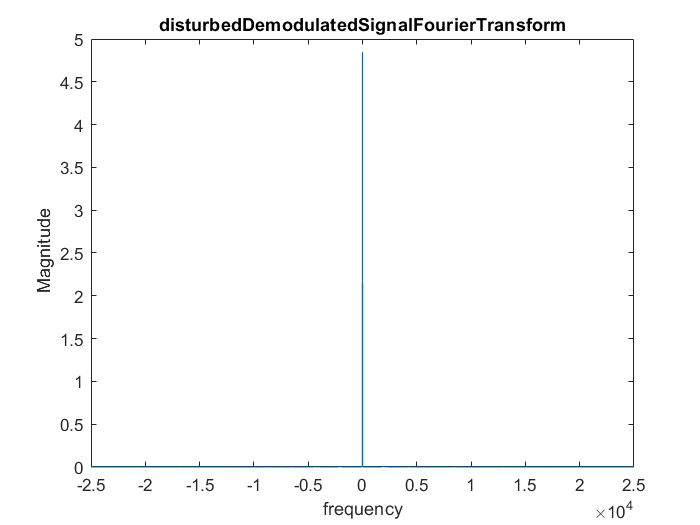


[disturbedDemoduleFourierTransform,freq] = standardFourierTransform(demodul,fs);
plot(freq,abs(disturbedDemoduleFourierTransform));
title('disturbedDemodulatedSignalFourierTransform');
xlabel('frequency');
ylabel(' Magnitude');

tempX = x(1:length(demodul));
MSEerrorALLOfDomain = immse(demodul,transpose(tempX))

MSEerrorALLOfDomain = 3.8725e-04

MSEerrorCorrectDomain = immse(demodul(5001:2*5001),transpose(x(5001:2*5001)))

MSEerrorCorrectDomain = 4.2797e-05

function [out,standardDomain] = standardFourierTransform(signal,fs)
n = length(signal);
fourier=fft(signal,n);
fourier = fourier/fs;
out = fftshift(fourier);
domain = linspace(-pi,pi,length(out));
standardDomain = domain*fs/(2*pi);
end

function [out,Tsignal] = sdf(signal)
Tsignal = fourierDiscreteStandardTransform(signal);
out = Tsignal.*conj(Tsignal);
end

function out = fourierDiscreteStandardTransform(signal)
out = fftshift(fft(signal,size(signal,2)));
end

function boundedEnergy = calEnergy(powerSignal,center,range)
boundedEnergy = sum(powerSignal(center-range:center+range));
end

function filt = delaySyncer(y,Hf)
temp = filter(Hf,1,y);
delay = mean(grpdelay(Hf,1));
filt =temp;
filt(1:delay) = [];
end


function integral = Integral(signal,fs)
integral = zeros(1,length(signal));
for i = 2 : length(signal)
    integral(1,i) = integral(1,i-1) + ( signal(i) + signal(i-1) )/(2*fs);
end
end


function derive = derivative(signal,fs)
derive = zeros(1,length(signal));
for i=2:length(signal)-1
    derive(i) = (signal(i+1)-signal(i-1))*fs/2;
end
end